%{
Name: Streetlight Brightness Model
Author: Evan Scheuritzel
Version: 1.0
Purpose: Determine when two streetlights have equal brightnesses.
Input: none
Output: Graph showing brightness over distance curves, and intersection
point
%}

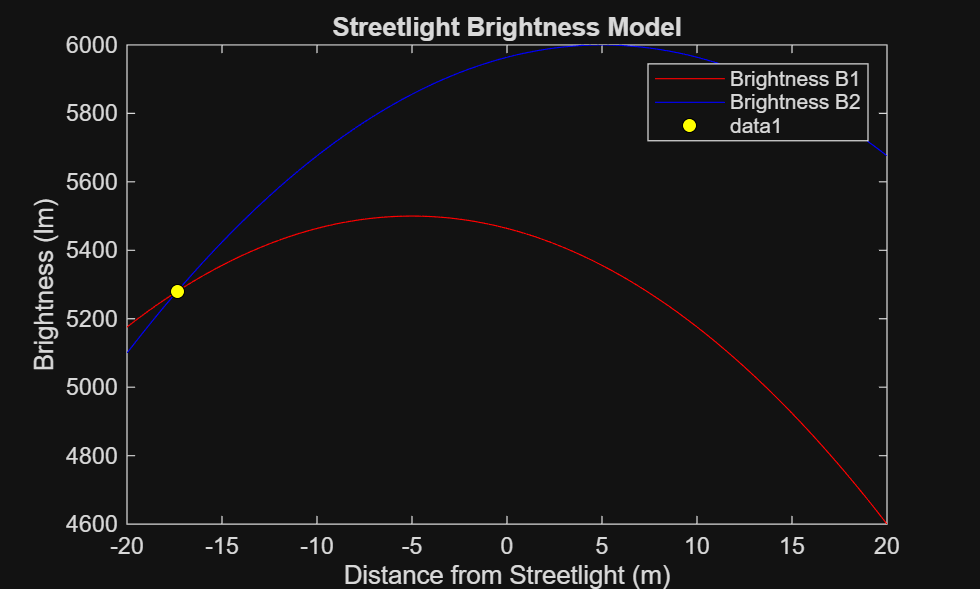

    x_equal    Brightness
    _______    __________

    -17.361      5279.9  



clearx = -20:.5:20;
k = 1.44;
h1=-5;
h2=5;
% Average street light brightness
maxB1 = 5500;

maxB2 = 6000;
B1 = -k*(x-h1).^2+maxB1;
B2 = -k*(x-h2).^2+maxB2;
plot(x,B1,'red')
hold on;
plot(x, B2, 'blue');
xlabel('Distance from Streetlight (m)');
ylabel('Brightness (lm)');
title('Streetlight Brightness Model');
legend('Brightness B1', 'Brightness B2');
% Find x locations where B1 == B2
diffB = B1 - B2;
% Find sign changes (roots) of diffB
idx = find(diffB(1:end-1).*diffB(2:end) <= 0);
x_eq = [];
for i = idx
    % Linear interpolation between x(i) and x(i+1) to estimate root
    x1 = x(i); x2 = x(i+1);
    y1 = diffB(i); y2 = diffB(i+1);
    if y2==y1
        xr = (x1+x2)/2;
    else
        xr = x1 - y1*(x2-x1)/(y2-y1);
    end
    x_eq(end+1) = xr; %#ok<SAGROW>
end

% Display and mark the intersection points
if isempty(x_eq)
    disp('No intersection points found within x range.')
else
    y_eq = interp1(x, B1, x_eq); % common brightness values
    disp(table(x_eq.', y_eq.', 'VariableNames', {'x_equal','Brightness'}))
    plot(x_eq, y_eq, 'ko', 'MarkerFaceColor','y')
end